# Correlation tryout

## Load the base wave file that is been send to the other components and display

Load the base signaling data and set it to 1kHz sample rate.

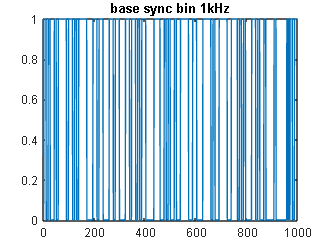

clc, clear;

filename = 'DATASET\pianosync.wav';
[y,Fs] = audioread(filename); % 8kHz sample 
%plot(y(1:2000, 1));
%title(".wav signal of 8kHz")

% pianosinc to 1kHz
%base_wave_1k = decimate(y(:,1)', 8);

base_wave_1k = SigConToBin(y(:, 1)', 8000, 1000);

plot(base_wave_1k(1:1000));
title("base sync bin 1kHz");

## Load the motion tracking data and resample to 1kHz and display

Add path of the function

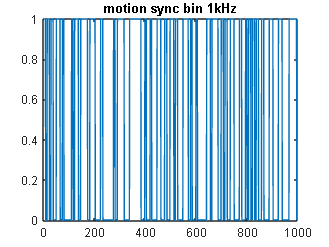

addpath OTHER\
% Add path of 
% use this function example  
% 'data = BinToQTM(elina3.Trajectories.Unidentified.Data, [637.1 457.7 193.6], [10 10 10]);'

raw_video_data = load("DATASET\elina3_nogapfilling.mat");
poi = [637.1 457.7 193.6];
tolerance_poi = [10 10 10];

video_capture_300 = double(QTMToBin(raw_video_data.elina3.Trajectories.Unidentified.Data, poi, tolerance_poi));

video_capture_1k = SigConToBin(video_capture_300, 1000, 1000);

plot(video_capture_1k(1:1000));
title("motion sync bin 1kHz");

## Difference with base and video capture

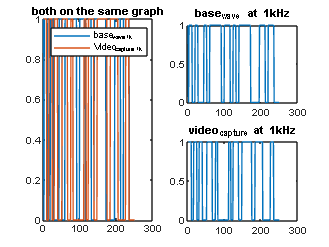

t = 1:250;
subplot(2,2,[1 3]);
plot(t, base_wave_1k(t), t, video_capture_1k(t));
legend("base_wave_1k", "Video_capture_1k");
title("both on the same graph")
subplot(2,2,2);

plot(t, base_wave_1k(t));
title("base_wave at 1kHz");

subplot(2,2,4);
plot(t, video_capture_1k(t));
title("video_capture at 1kHz");

## Load blood data and display

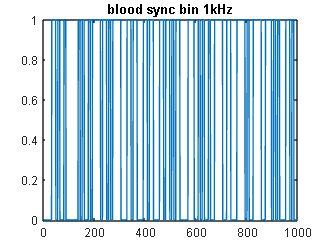

raw_blood_data = load("DATASET\perfusion_and_sync_19-Dec-2023-11_15_20.mat");
raw_blood_data_sync_1k = raw_blood_data.fullDataSet(:, 1)';

%plot(raw_blood_data_sync_1k(1:400));

raw_blood_data_sync_1k = SigConToBin(raw_blood_data_sync_1k, 1000,1000);

subplot(1,1,1);
plot(raw_blood_data_sync_1k(1:1000));
title("blood sync bin 1kHz");

## Load EMG data and display

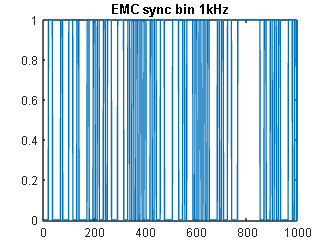


filename = 'DATASET\opensignals_000780589b3a_2023-12-19_11-12-23.txt';
data = readmatrix(filename, 'Range', 4, 'Delimiter', '\t');

emg_sync = data(:, 3);
emg_sync_1k = SigConToBin(emg_sync, 1000,1000);

plot(emg_sync_1k(1:1000));
title("EMC sync bin 1kHz");